# Demo 1: Solving the NUDFT problem using three methods

#### Low Rank Approximation method (LRA): `Ruiz-Antolin, D., & Townsend, A. (2017). A nonuniform fast Fourier transform based on low rank approximation. http://arxiv.org/abs/1701.04492`

#### Guassian Interpolation method (GI): `Greengard, L., & Lee, J. Y. (2004). Accelerating the nonuniform fast Fourier transform. SIAM Review, 46(3), 443–454. https://doi.org/10.1137/S003614450343200X`

#### Optimization method (Opt): `proposed by us`

clear;
clf;
addpath('./utils');

% Set random seed
rng(57);

% Parameters
N = 2^10;
M = N;

% Non-uniform space sampling and uniform frequencies
x = rand(N,1);
x = sort(x);
w = (-M/2:M/2-1)';

% Test vectors
T = 100;
c = rand(N,T);
c = c / norm(c,2);

% Calculation
% 0. exact NUDFT
f_ds = exact_nudft(c,x,M);

% 1. Low Rank Approximation method -- Complexity: O( R*M*log(M) + M + N )
R_lra = 12;
f_lra = lra_method(c,x,M,R_lra);

% 2. Guassian Interpolation method -- Complexity: O( R*M*log(R*M) + M + S*N )
R_gi = 1.5;
S_gi = 21;
tau_gi = (1/M^2)*(pi*(S_gi-1)/2)/(R_gi*(R_gi-0.5));
f_gi = gi_method(c,x,M,R_gi,S_gi,tau_gi);

% 3. Optimization method -- Complexity: O( R*M*log(R*M) + M + S*N )
R_opt = 1.5;
S_opt = 21;
init = "gi";  % "gi"(recommended), "eye" or "randn"
order = "B-first";  % "B-first" or "D-first"
N_iter = 5;
display = false;
[D_opt,F_opt,B_opt,~,~] = optimization_nufft(x,M,R_opt,S_opt,init,order,N_iter,display);
f_opt = opt_method(c,D_opt,F_opt,B_opt);

% Mean relative error L2-norm
e_lra = mean_relative_error_norm(f_lra,f_ds);
e_gi = mean_relative_error_norm(f_gi,f_ds);
e_opt = mean_relative_error_norm(f_opt,f_ds);
fprintf(['Mean relative error L2-norm on %d test vectors:\n', ...
         '  Low Rank Approximation method:  %.2e\n', ...
         '  Guassian Interpolation method:  %.2e\n', ...
         '  Optimization method:            %.2e\n'], ...
        [T,e_lra,e_gi,e_opt]);

Mean relative error L2-norm on 100 test vectors:
  Low Rank Approximation method:  1.44e-08
  Guassian Interpolation method:  1.50e-08
  Optimization method:            7.17e-11


# Demo 2: Exploration of LRA method

#### The decay rate of singular values of matrix $K./F$ (how low the numerical rank of the matrix is)  shows the bottleneck of LRA method.

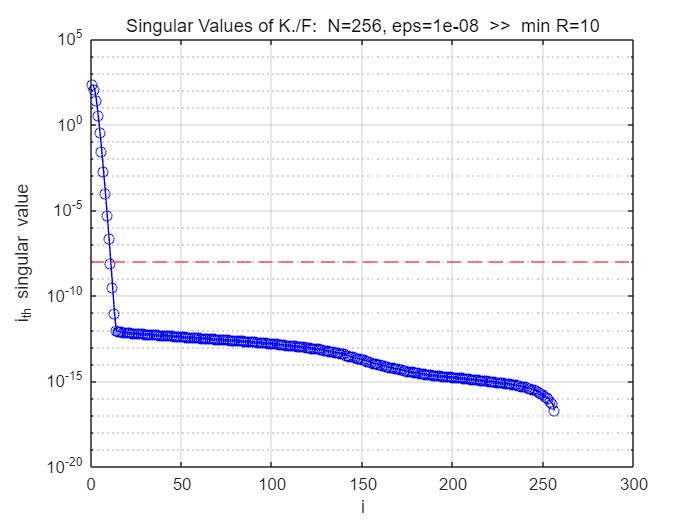

clear;
clf;

% Set random seed
rng(57);

% Parameters     
N = 2^8;
M = N;

% Non-uniform space sampling
x = rand(N,1);
x = sort(x);

display = true;
eps = 1e-8;
min_R = sv_lra(x,M,display,eps);

# Demo 3: Experiments of Optimization method

## Experiment 1: Number of iterations

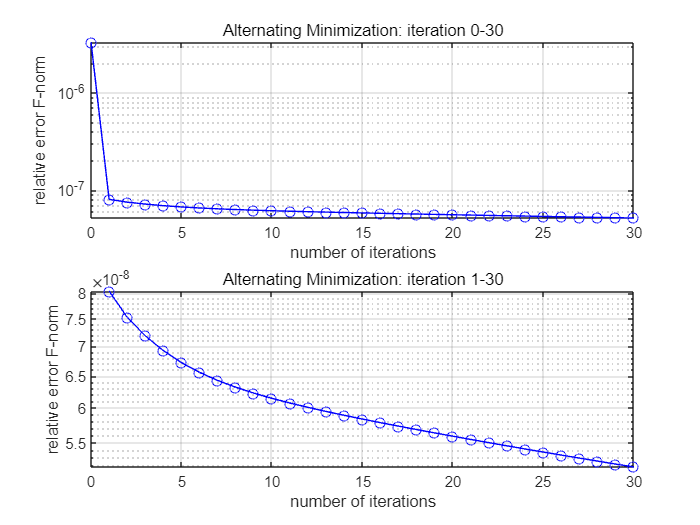

Initial relative error F-norm:   3.33e-06
Ultimate relative error F-norm:  5.17e-08


clear;
clf;

% Set random seed
rng(57);

% Parameters
N = 2^8;
M = N;
R = 1.5;
S = 15;

% Non-uniform space sampling
x = rand(N,1);
x = sort(x);

% Optimization method
init = "gi";  % "gi"(recommended), "eye" or "randn"
order = "B-first";  % "B-first" or "D-first"
N_iter = 30;
display = true;
[~,~,~,~,~] = optimization_nufft(x,M,R,S,init,order,N_iter,display);

## Experiment 2: Initialization method

init_list = ["gi"; "eye"; "randn"];
order = "B-first";  % "B-first" or "D-first"
N_iter = 5;
display = false;

for i = 1:3
    init = init_list(i);
    [~,~,~,e_init,e_ulti] = optimization_nufft(x,M,R,S,init,order,N_iter,display);
    fprintf(['Initialization method: %s\n', ...
             '  Initial relative error F-norm:   %.2e\n', ...
             '  Ultimate relative error F-norm:  %.2e\n'], ...
            [init,e_init,e_ulti])
end

Initialization method: gi
  Initial relative error F-norm:   3.33e-06
  Ultimate relative error F-norm:  6.72e-08
Initialization method: eye
  Initial relative error F-norm:   3.95e+00
  Ultimate relative error F-norm:  3.06e-05
Initialization method: randn
  Initial relative error F-norm:   4.04e+00
  Ultimate relative error F-norm:  6.90e-02


## Experiment 3: Order of alternating minimization

init = "gi";  % "gi"(recommended), "eye" or "randn"
order_list = ["B-first", "D-first"];
N_iter = 5;
display = false;
for i = 1:2
    order = order_list(i);
    [~,~,~,e_init,e_ulti] = optimization_nufft(x,M,R,S,init,order,N_iter,display);
    fprintf(['Order of alternating minimization -- %s\n', ...
             '  Initial relative error F-norm:   %.2e\n', ...
             '  Ultimate relative error F-norm:  %.2e\n'], ...
            [order,e_init,e_ulti])
end

Order of alternating minimization -- B-first
  Initial relative error F-norm:   3.33e-06
  Ultimate relative error F-norm:  6.72e-08
Order of alternating minimization -- D-first
  Initial relative error F-norm:   3.33e-06
  Ultimate relative error F-norm:  6.89e-08


# Demo 4: Comparison of GI method and Optimization method

clear;
clf;

% Set random seed
rng(57);

% Parameters
N = 2^8;
M = N;

% Non-uniform space sampling
x = rand(N,1);
x = sort(x);

warning('off','all')
init = "gi";
order = "B-first";  % "B-first" or "D-first"
N_iter = 5;
display = false;

R_list = 1 + 1./(2.^(-1:4));
S_list = (1:2:50);
N_R = length(R_list);
N_S = length(S_list);
e = zeros(N_S+1,3*N_R); % record the precision of GI method and Optimization method at different settings

tic;
for i = 1:N_R
    R = R_list(i);
    e(1,3*i-2) = R;
    for j = 1:N_S
        S = S_list(j);
        [~,~,~,e_init,e_ulti] = optimization_nufft(x,M,R,S,init,order,N_iter,display);
        e(j+1,3*i-2:3*i) = [S,e_init,e_ulti];
    end
end
time = toc;
fprintf('Running Time: %.2fs',time)

Running Time: 80.56s